# Multilevel mediation in fMRI

## Mediation analysis: The basics

Mediation is a useful tool for connecting variables into pathways. It extends the idea of a simple association between two variables (let's call them ***x*** and ***y****)* to a pathway involving three (or more) variables.  Let's write the association ***x*** predicts ***y*** like this: **[ *****x -> y ].***  This relationship is shown graphically in the diagram below:

Suppose we hypothesize that the effect of ***x*** on ***y*** is transmitted via its influence on an intermediate variable, ***m***.  With mediation analysis, you can build a model of associations among three variables, i.e., **[ *****x *****->***** m *****->***** y *****]**. ***m*** is a mediator, a variable that explains some or all of the relationship between ***x ***and ***y***.  

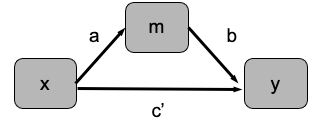

Mediation models are especially useful for developing models in which an association between two variables is transmitted via a third variable. For example, the effects of a psychological stressor (***x***) on heart rate (***y***) may be mediated by activity in brain systems responsible for threat. The stressor activates the brain, and the brain in turn controls the heart.  

In mediation analysis, ***x*** is called the *initial variable*. it will often be an experimental variable (IV) that is experimentally manipulated, but it doesn't have to be.  ***y*** is called the *outcome variable *(or *dependent variable*), and it is usually the endpoint that one is interested in explaining. m is the *mediator*, and is usually a variable that is thought to be important for transmitting the effect of ***x*** on ***y, ***or on the "causal path" from ***x ***to*** y. ***It is also possible to include multiple initial variables, multiple mediators, and other covariates in such models. The broader family that the [ *x *->* m *->* y *] model belongs to is called **path models****.**

Here are some other examples. Exercise may improve memory via neurogenesis.  Exercise causes new neurons to be generated in the brain, which helps the brain form new memories more efficiently.  here, ***x*** is exercise, ***m*** is neurogenesis, and ***y*** is memory. Smoking (***x***) may lead to premature death (***y***) via increased rates of cancer (***m***). 

### **Estimating path models and statistical inference**

Testing for mediation involves fitting two linear regression equations. The slopes (coefficients) of these equations are called *paths*, and the estimated regression coefficients are *path coefficients*. 

There are three path coefficients in the model above. The path coefficient *a* captures the effect of ***x*** on ***m*** (e.g., smoking on cancer in the example above).  This is estimated by the first equation. The path coefficient ***b*** captures the effect of ***m*** on ***y*** (e.g., cancer on mortality in the example above), and the coefficient ***c’*** the *direct effect* of ***x*** on ***y*** after controlling for ***m***.  The path through ***m*** is called the *indirect pathway*, and the mediation via M the *indirect effect*. Statistical inference on this pathway is made by testing the product of the ***a*** and ***b*** path coefficients.

 The equations are:


$$M=aX+d_1$$
 


$$Y=bM+c'X+d_2$$


To test mediation, we estimate both of these equations, calculate the ***a*b*** product, and turn this into an inferential statistic (e.g., a *t* statistic) by dividing by an estimate of its standard error. The [Sobel test ](http://quantpsy.org/sobel/sobel.htm)is one way of doing this using a formula, but it is only asymptotically accurate in large samples and depends strongly on assumptions of normality. In practice, it is typically overconservative. Mediation is more commonly tested using bootstrapping, as described in [Shrout and Bolger (2002)](https://psycnet.apa.org/doiLanding?doi=10.1037%2F1082-989X.7.4.422%7D,).

Here is an example of a bootstrapped distribution for the indirect effect from the [M3 Mediation Toolbox](https://github.com/canlab/MediationToolbox). This distribution provides confidence intervals and P-values for the ***a*b*** effect and other path coefficients:

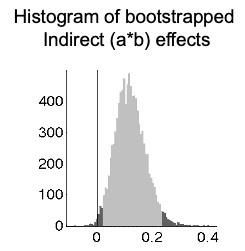

The dark shading shows the top and bottom 2.5% of the distribution, and thus the 95% confidence interval for ***a*b***. If 0 falls outside of this (in the dark gray zone), the effect is significant at P < 0.05. 

In whole-brain mediation analysis, we bootstrap path coefficients and the mediation effect at each brain voxel, and save maps of P-values. These are subjected to voxel-wise [False Discovery Rate correction](https://rss.onlinelibrary.wiley.com/doi/abs/10.1111/j.2517-6161.1995.tb02031.x) to correct for multiple comparisons.

### Counterfactual interpretation of mediation

A way of understanding the mediation effect is in terms of a counterfactual: What ***x -> y ***association *would we have* observed if we had prevented ***m*** from varying?  

We can't directly observe the counterfactual case, but we can test the difference between the simple ***x -> y ****effect* when we don't control for the mediator (***Path c*** in the figure above) with the ***x -> y ****effect* when we **do** control for the mediator (***Path c'***). Thus, we want to statistically test whether c - c' = 0.  

It turns out that with a little algebraic manipulation, we can show that:


$$c-c'=a*b$$


So a statistical test of ***a*b*** is the same as comparing the effect of ***x*** on ***y*** across two models: One in which the mediator can vary, and one in which it's statistically adjusted for -- the regression equivalent of holding it constant.

**The M3 Mediation Toolbox**

The [multilevel mediation and moderation (M3) toolbox](https://github.com/canlab/MediationToolbox) is a Matlab toolbox designed to permit tests of both single-level and multi-level models. 

### **A note on causality** 

Mediation models of the type we explore here (and path models more generally) are build on linear regression, with the same assumptions and limitations of other linear models. It is a directional model: As with a standard multiple regression model, we are explaining ***y*** as a function of ***x*** and ***m***. And, as with standard regression, the presence of a statistical association does not provide direct information on causality. The observed relationships could, in principle, be caused by other variables that are not included in the model (i.e., lurking variables or common causes), and/or the direction of causality can be reversed from how you've formulated it in the model.  

Experimental manipulation of variables can provide stronger evidence for causal associations, and sometimes both ***x*** and ***m*** are experimentally manipulated. This is a major strength of experimental methods across all disciplines! However, when variables are observed rather than manipulated, statistical associations very rarely provide strong information about causality. In particular, when ***x*** and ***m*** are both observed (not manipulated), reversing the mediation (i.e., swapping ***x*** and ***m***) is not a good way to determine what the form of the model should be. This is because differences in relative error (or reliability) could make one model fit better than another, irrespective of the true causality. 

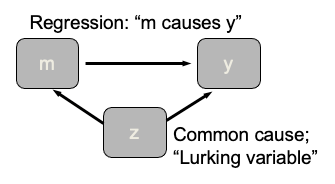

An alternative to the linear model approach we describe here is the [causal mediation framework](https://www.publichealth.columbia.edu/research/population-health-methods/causal-mediation), which makes the assumptions required for causal inference more explicit, and provides tests for mediation based on conditional probabilty (essentially, stratification). One entry point for this is [Robins and Greenland (1992)](https://www.jstor.org/stable/3702894?seq=1#metadata_info_tab_contents) and [Pearl (2014)](https://psycnet.apa.org/buy/2014-21922-001). However, there is no "magic bullet" for assuring causality if the assumptions underlying causal inference might not be valid. It's worth taking a closer look at these here. To infer causality, we need more than just the variables we're measuring: We need solid information about the broader system in which the variables are embedded.

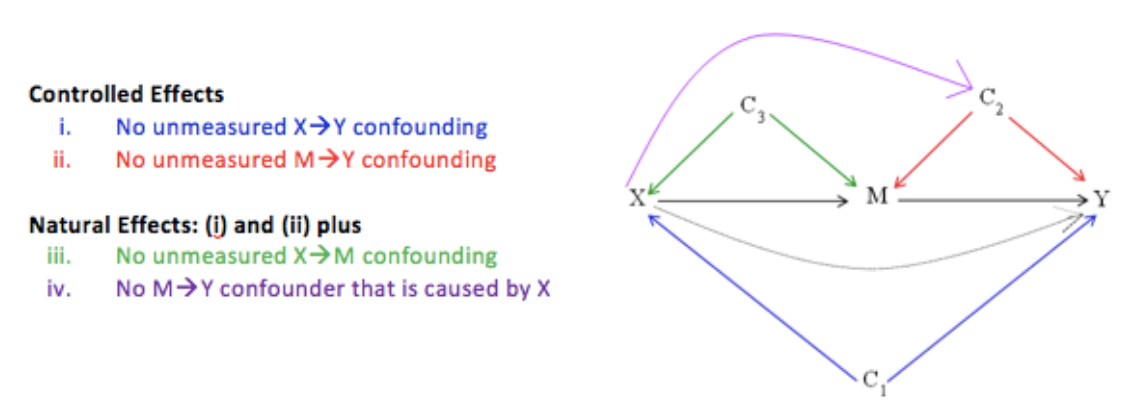

The image shown below is from the [Columbia causal mediation website](https://www.publichealth.columbia.edu/research/population-health-methods/causal-mediation).  

#### Further reading

More details on basic principles of mediation, with references, can be found on [David Kenny's excellent web page](http://davidakenny.net/cm/mediate.htm), and in a number of papers and books (e.g., [MacKinnon 2008](https://www.taylorfrancis.com/books/mono/10.4324/9780203809556/introduction-statistical-mediation-analysis-david-mackinnon)).

## Multilevel mediation

In the standard mediation model, each of X, M, and Y are vectors with one observation per person. Thus, the individual participant is the unit of observation. When this is the case, we'll call this a **single-level** mediation. 99% or so of the mediation analyses in the literature are single-level models.  For example, X can include a vector of individuals who are either smokers (coded as 1) or non-smokers (coded as -1), and we include measures of both the incidence of cancer (M) and survival time (Y) for each person.

What happens if we have repeated observations of X, Y, and M within a person?  This allows us to estimate the Path a, Path b, and a*b effects within each person.  This allows each person "to serve as their own control", and eliminates a number of person-level confounds and noise. For example, in our cancer example above, people will likely vary in their diet, and diet could be correlated with smoking, introducing a potential confound (or "3rd variable") and at the least an additional source of uncontrolled noise.  In a mulitlevel model, we can estimate the effect within-person, and test the significance of the path coefficients across individuals, treating participant as a random effect. This reduces the chances that the mediation effect is related to a 3rd variable, and allows us to generalize the effect across a population with a range of diets (and other person-level characteristics). This can often dramatically increase the power and validity of a mediation model.

In addition, with multilevel mediation, we can include person-level covariates in the model as well. For example, we can test whether diet moderates (influences) the effects of smoking on cancer (Path a), the effects of cancer on mortality (Path b), or the mediation (a*b) effect.  This is called moderated mediation. Thus, multilevel mediation allows us to include two kinds of variables in the same model: within-person variables that are measured for each person, and between-person (or person-level) variables that are measured once for a person. We can make inferences on the within-person mediation effect and test whether it generalizes over or is moderated by person-level characteristics. 

Single-level (standard) and multilevel mediation with all of these variations is implemented in the [Multilevel Mediation and Moderation (M3) Matlab Toolbox](https://github.com/canlab/MediationToolbox).

### Brain mediators and mediation effect parametric mapping (MEPM)

Multilevel mediation models are fairly rare in the social sciences, but in fMRI studies of cognitive and affective tasks, they are a natural fit.  We often manipulate tasks and observe both brain activity and behavioral responses (e.g., ratings or performance) within-person across time.  This makes multilevel mediation a natural fit to analyze experimental effects on the brain and their relationships with behavior in a single model. We can even add person-level characteristics like patient status or personality into the model as well.  

The mediation model we'll explore in this tutorial looks like this:

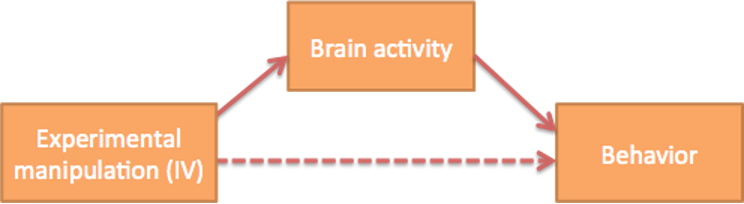		

		    X                                                M                                                   Y

X represents the task condition -- e.g., in our example below, the temperature of a hot stimulus applied to the skin. It is often coded with 1 or -1 ("effects coding") when there are two conditions, but can be coded with linear contrast codes or other numerical values when there are more than two conditions. M represents fMRI activity.  Y represents a behavioral outcome of interest.

Here, for our neuroimaging multilevel mediation tutorial, we'll extend this in two ways:

- We'll search over brain voxels, testing each voxel in an fMRI study as a mediator one at a time. We'll then save maps of how strong the mediation effect is.

- We'll change the unit of observation from the participant to conditions within-participant.  This is possible because in fMRI, we typically we vary X within-person by including different experimental tasks that might impact M and Y. We can also observe fMRI acitivity (M) and behavior (Y) as they vary within-person.  When we model these within-person relationships and perform statistical tests to generalize the associations to a population of individuals, we are performing multilevel mediation.   				

The [Multilevel Mediation and Moderation (M3) Matlab Toolbox](https://github.com/canlab/MediationToolbox) will perform both single- and multilevel mediation. The function **mediation.m** can operate on any type of input data (behavior, psychosocial measures, physiology, brain, genetics, etc.), and will run both single and multilevel mediation depending on the input data.

The toolbox also has special functions for running mediation on each voxel in a neuroimaging dataset (single or multilevel) and saving maps of mediation effects:

### About the dataset

This dataset includes 33 participants, each with brain responses to six levels

of heat (44.3 - 49.3 degrees C in one degree increments, which generally span the range from non-painful to painful). For each participant, a .nii image is included with 6 brain volumes (one per intensity level, in ascending order). These model the average activity during painful stimulation, assuming the standard canonical HRF, and were estimated using first-level models in SPM8. A metadata file includes the temperature and average pain rating per subject per temperature. 

Aspects of this data appear in these papers, among others:

[Wager, T.D., Atlas, L.T., Lindquist, M.A., Roy, M., Choong-Wan, W., Kross, E. (2013). An fMRI-Based Neurologic Signature of Physical Pain. The New England Journal of Medicine. 368:1388-1397](https://www.nejm.org/doi/full/10.1056/nejmoa1204471)

(This study is Study 2 of the paper).

[Woo, C. -W., Roy, M., Buhle, J. T. & Wager, T. D. (2015). Distinct brain systems mediate the effects of nociceptive input and self-regulation on pain. PLOS Biology. 13(1):e1002036. doi:10.1371/journal.pbio.1002036](https://journals.plos.org/plosbiology/article?id=10.1371/journal.pbio.1002036)

[Lindquist, Martin A., Anjali Krishnan, Marina López-Solà, Marieke Jepma, Choong-Wan Woo, Leonie Koban, Mathieu Roy, et al. 2017. Group-Regularized Individual Prediction: Theory and Application to Pain. NeuroImage. 145:274-287.](https://www.sciencedirect.com/science/article/pii/S1053811915009982) 

[Stephan Geuter, Elizabeth A Reynolds Losin, Mathieu Roy, Lauren Y Atlas, Liane Schmidt, Anjali Krishnan, Leonie Koban, Tor D Wager, Martin A Lindquist, Multiple Brain Networks Mediating Stimulus–Pain Relationships in Humans, Cerebral Cortex, Volume 30, Issue 7, July 2020, Pages 4204–4219.](https://academic.oup.com/cercor/article/30/7/4204/5811924?login=true)

The dataset is available in CANlab Core toolbox under "Sample_Datasets/Woo_2015_PlosBio_BMRK3_pain_6levels". BMRK3 is the CANlab study code for this study. It was collected by Mathieu Roy, Jason Buhle, and research assistants in the CANlab.

### Using the dataset to demonstrate mulitlevel mediation

This dataset provides a lightweight, minimally viable dataset to demonstrate multilevel mediation. Usually, a mulitlevel mediation dataset would include more than 6 images per person -- for example, it might include trial-level data (as in Atlas et al. 2010, 2014; Koban et al. 2019) or full time series data (as in Wager et al. 2009).

Here, the variable **temperatures** will serve as the initial variable (X), **ratings** will serve as the outcome variable (Y), and brain images, whose names are stored in a variable called **single_trial_image_names**, will serve as the mediator (M).  Thus, the analysis will search over brain voxels and test whether each voxel's response during pain mediates the effects of temperature on pain ratings: 

***[temp (X) -> brain activity during pain (M) -> pain ratings (Y)]***

The function `mediation_brain_multilevel` will take in a set of image names in place of either X, Y, or M. 

The format is that each of X, Y, and M are cell arrays, with one cell per subject.  Each cell should contain either a column vector of values (for numeric variables) or a list of image names or 4D image for brain image inputs.

### Load the dataset

Locally or from the web					

metadata_file = which('bmrk3_6levels_metadata.mat');
metadata_file

metadata_file = '/Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Woo_2015_PlosBio_BMRK3_pain_6levels/bmrk3_6levels_metadata.mat'


if isempty(metadata_file)

    disp('You need the dataset Woo_2015_PlosBio_BMRK3_pain_6levels on your Matlab path.')
    disp('This is in the CANlab Core toolbox.')
    error('Check path and files.')
end

load(metadata_file);

% Re-find local path names for brain images
M = single_trial_image_names;

dir_old = fileparts(M{1});
dir_new = fileparts(metadata_file);

for i = 1:length(M), M{i} = strrep(M{i}, dir_old, dir_new); end

X = temperatures;
Y = ratings;

whos X Y M

  Name      Size            Bytes  Class    Attributes

  M         1x33            12342  cell               
  X         1x33             5016  cell               
  Y         1x33             5016  cell               



### Set up and run multilevel mediation

Most of the heavy lifting is done here. There are three steps:

- Create a mediation directory to save output, and go there

- Configure setup options in a SETUP structure

- Run mediation (this will save files to disk)

*Note*: The mask will likely have to be resliced (resampled and interpolated) to match the origin and dimensions of the brain dataset.

mkdir mediation_results

Calculating FDR threshold across family of tests in these images:
X-M_pvals.img  
M-Y_pvals.img  
X-M-Y_pvals.img
Total p-values:  586836
FDR threshold is 0.003370
Saving in SETUP.fdr_p_thresh


cd mediation_results

SETUP.mask = which('gray_matter_mask.nii');
SETUP.preprocX = 0;
SETUP.preprocY = 0;
SETUP.preprocM = 0;

% mediation_brain_multilevel(X, Y, M, [other inputs])
mediation_brain_multilevel(temperatures, ratings, single_trial_image_names, SETUP);


`mediation_brain_multilevel `saves a SETUP file with the input variables and estimated results maps for all the relevant effects. You can save the files in directory and use them to make tables and figures of results at any time later. Here are some of the key files:

X-M_effect.img                        Map of average slope coefficients for Path a 

M-Y_effect.img                        Map of average slope coefficients for Path b

X-M-Y_effect.img                    Map of average slope coefficients for Path a*b (mediation effect)

X-M_indiv_effect.img              4D image wtih individual slope coefficients for Path a (one image per participant)

M-Y_indiv_effect.img              4D image wtih individual slope coefficients for Path b (one image per participant)

X-M-Y_indiv_effect.img           4D image wtih individual slope coefficients for Path a*b (one image / participant)

X-M_ste.img                            Standard error for Path a (across participants)

M-Y_ste, X-M-Y_ste.img        Standard errors for Path b and a*b effects (across participants)

X-M_indiv_ste.img                 4D image wtih individual standard errors for Path a (one image per participant)

M-Y_indiv_ste.img, X-M-Y...   Individual standard errors for Path b and a*b (one image per participant

X-M_pvals.img                       Map of P-values for Path a 

M-Y_pvals.img, X-M-Y...         Maps of P-values for Paths b and a*b

Once results scripts have been run (e.g., with `mediation_brain_results`; see below), additional output will be generated. This includes printouts of slice montages (.png graphics) and tables with thresholded results. An example of these looks like this:

M-Y_pvals_005_k5_noprune_log.txt

M-Y_pvals_005_k5_noprune_results.txt

## Multilevel mediation results: Viewing and saving 

Once you've completed a successful run of `mediation_brain_multilevel`, you can go to the results directory and examine the results.  The goal of this section is to construct and save:

- Figures showing significant regions

- Significant "blobs" (clusters) with extracted data (cl* below)

- Tables of significant regions with mediation statistics

We can get results on significant regions for each of the Path a, Path b, and Path a*b (mediation effect) maps.

- The*** Path a*** map tests the effect of X (temperature) on M (brain responses)

- The ***Path b*** map tests the effect of M (brain responses) on Y (ratings) controlling for X (temperature)

- The ***Path a*b*** (mediation) map tests the product of a and b, or (equivalently) whether M (brain) explains a significant amount of the covariance between X and Y.

For a single-level mediation, the thresholded ***Path a*b ***map (showing signifcant voxels) will always include a subset of the voxels significant in the ***Path a ******and****** Path b ***maps. 

For a multilevel mediation, this is not necessarily the case. This is because the significance of the a*b mediation effect is based on the strength of the average a effect, the average b effect, and the covariance between them. This is explained by [Kenny, Korchmaros, and Bolger (2003)](https://psycnet.apa.org/buy/2003-06499-003), a seminal paper on mulitlevel mediation. It's discussed in relation to brain maps in [Atlas et al. 2010](https://www.jneurosci.org/content/30/39/12964.short).  

This means that you might be interested in looking at each of the maps, as each provides a different and complimentary piece of information.

*Note*: You don't need to have run the mediation in the same Matlab session to use these results functions. You just need to be in a valid mediation results directory with saved maps.

*Note*: To extract data from significant clusters (regions), save it in clusters structures (see below), and generate the most complete tables of mediation results, you do need to have access to the original data files used to run the mediation. Their names are stored (for this example, with brain images as mediator) in SETUP.data.M.  If you move the images or results directory, you may need to replace this field with the updated file names for full functionality.

### Choosing a threshold

We'll need to specify a significance threshold, entered as a P-value threshold. The function below chooses a threshold that satisfies FDR on average across the Path a, b, and a*b maps. 

There are other thresholding options as well.  We could also choose an uncorrected P-value threshold to be entered into the `mediation_brain_results `function below. 

SETUP = mediation_brain_corrected_threshold('fdr');

This gives us an equivalent P-value to satisfy FDR-corrected at q < 0.05 on average across the 3 maps, which is stored in SETUP.fdr_p_thresh.  It will be *Inf* if there is not enough signal to meet the threshold.

*Note*: P-values are always two-tailed, unlike SPM P-values, which are one-tailed. So P < 0.002 here is equivalent to P < 0.001 using SPM.

**Multi-thresholding and 'pruned' significant regions**

We can choose a *series* of P-value thresholds if we want to save clusters ('blobs') where at least one voxel meets the most stringent threshold, but show continguous voxels in the cluster down to the most liberal threshold. We call this 'pruned' clusters, because we're thresholding a liberal display threshold but 'pruning' the set of significant regions so that each region has at least one voxel at the most stringent (often corrected) threshold. This can be useful for display and in particular for showing the extent of regions around the most stringent value.  For example, entering these options into `mediation_brain_results `will show us clusters where at least one voxel is FDR-corrected at q < 0.05 (map-wise), but we'll see the extent of each blob down to p < 0.005 as long as there are 3 contiguous voxels at that threshold (that are also contiguous with FDR-corrected results) and down to p < 0.01 uncorrected as long as there are at least 10 contiguous voxels. 

**Other preliminary stuff**

Let's define some variables that we can use to print nice headers in the report:

dashes = '----------------------------------------------';
printstr = @(dashes) disp(dashes);
printhdr = @(str) fprintf('\n\n%s\n%s\n%s\n%s\n%s\n\n', dashes, dashes, str, dashes, dashes);

### Results for Path a

The code below generates results for Path a, the effects of stimulus temperature on brain activity, within-person, estimated across the 6 temperatures and 6 brain images per participant. Results and P-values reflect population inference, treating participant as a random effect.  

`mediation_brain_results `can accept various input options.  As with all functions, help <function_name> (e.g., help mediation_brain_results) will explain the full set of options. Here, we'll use the average FDR-corrected threshold from above, and keywords that generate slices and tables, and save results output. The output will be shown on the screen, printed to the command window, and saved in files in the mediation results directory. The output variables clpos, etc. are clusters structures that can be used in interactive follow-up analyses and plots (we'll explain these below).

printhdr('Path a: Temperature to Brain Response')

----------------------------------------------
----------------------------------------------
Path a: Temperature to Brain Response
----------------------------------------------
----------------------------------------------




mediation_brain_results('a', 'thresh', ...
    SETUP.fdr_p_thresh, 'size', 5, ...
    'slices', 'tables', 'names', 'save');

Will show slices.
Will print tables.
Saving log file: X-M_pvals_003_k5_noprune_log.txt
Other key results in: X-M_pvals_003_k5_noprune_results.txt
Will also save figures of slice montages if 'slices' requested.

iimg_multi_threshold viewer
Showing positive or negative: pos
Overlay is: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/SPM8_colin27T1_seg.img
No mask specified in iimg_multi_threshold
Entered p-value image? : Yes
Height thresholds:0.0034 
Extent thresholds:   5 
Show only contiguous with seed regions: No
 
log(1/p) saved in output cl.Z field.


### Results for Path b

Generate results for effects of brain responses on pain reports, controlling for stimulus  temperature. 

printhdr('Path b: Brain Response to Pain, Adjusting for Temperature')

mediation_brain_results('b', 'thresh', ...
    SETUP.fdr_p_thresh, 'size', 5, ...
    'slices', 'tables', 'names', 'save');

### Results for Path a*b

Generate results for the mediation effect. Here, we'll return some clusters structures with results to the workspace as output so we can examine them later. (We can also load them from disk).

printhdr('Path a*b: Brain Mediators of Temperature Effects on Pain')


  Name              Size              Bytes  Class     Attributes

  clfilename        1x27                 54  char                
  clneg             1x1               24728  cell                
  clneg_data        1x33            1439194  cell                
  clneg_data2       1x7              103234  struct              
  clneg_extent      1x7               24624  struct              
  clpos             1x1               42432  cell                
  clpos_data        1x33            2472266  cell                
  clpos_data2       1x12             176498  struct              
  clpos_extent      1x12              42328  struct              



[clpos, clneg, clpos_data, clneg_data, clpos_data2, clneg_data2] = mediation_brain_results('ab', 'thresh', ...
    SETUP.fdr_p_thresh, 'size', 5, ...
    'slices', 'tables', 'names', 'save');

### Interactive data analysis: Using extracted clusters

The mediation toolbox saves output in standard formats that you can use in scripted or interactive analyses using other tools, including the [CANlab Core toolbox](https://github.com/canlab/CanlabCore).  CANlab Core is an [interactive, object-oriented toolbox](https://canlab.github.io/objectoriented/) written in Matlab. For more information on these tools and walkthroughs, see [canlab.github.io](http://canlab.github.io).  

A sample "road map" showing some of the things you can do with simple commands in the CANlab Core toolbox is below. These include surfaces, slices, and other visualization; tables of neuroimaging results labeled with reference atlases; data diagnostic plots; and statistical and machine learning analyses.

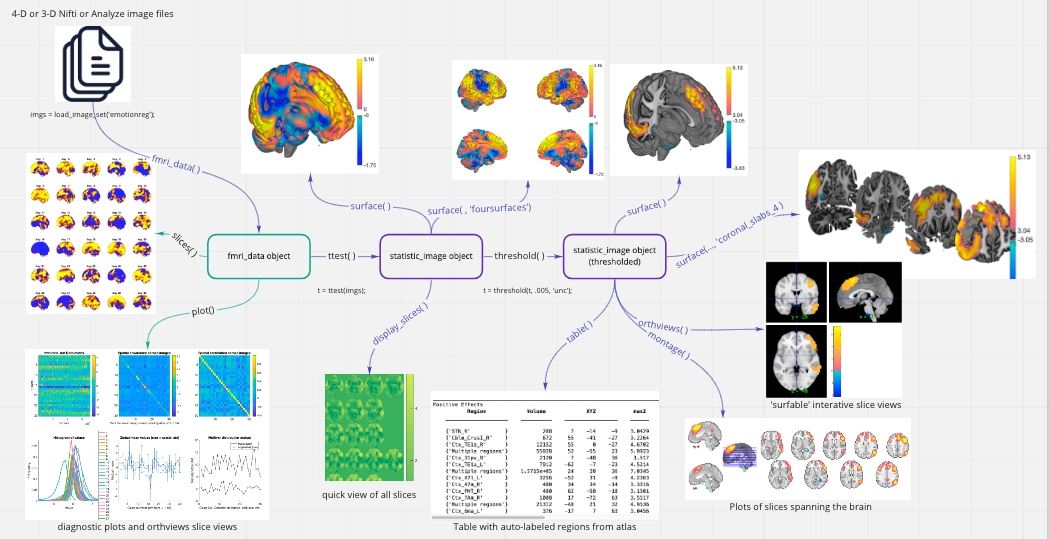

The mediation toolbox returns two kinds of outputs that you can use for a variety of analyses.  The first is .nii images saved to disk, which you can read and analyze using a variety of neuroimaging software applications. The second is "clusters" structures that return output to the workspace (and disk) that you can use for further visualization and analysis. 

The "clusters" structure, and it's newer object-oriented version in the  [CANlab Core toolbox](https://github.com/canlab/CanlabCore)--the ***region*** class object--is a data format that is designed to store information about contiguous suprathreshold (significant) regions ('blobs'). The cluster or region-class variable is a vector, with one element per brain region.  Within each element, a struct-format data structure describes the region, including its voxel locations, mapping from voxel to "world" (mm brain) space, statistics associated with each voxel and the region average, and potentially data for voxels or the region average that has been extracted from images and attached.

By default (if output variables are requested and it can find valid data input images), mediation_brain_results returns clusters for both positive and negative effects, with image data extracted for each region and averaged over in-region voxels. This allows you to examine and plot the data, and re-run a descriptive mediation analysis and mediation plots for any given region.  

More generally, once you have a clusters structure, you can do lots of things with it: 					

1. Extract data from any images you want and do ROI analysis (e.g., `extract_contrast_data`)

2. Plot blobs on orthviews (sections) or slices, with many options for display control with `cluster_orthviews`

3. Show them on a slice montage with `montage_clusters`

4. Make a table of coordinates, etc. with `cluster_table` or `mediation_brain_print_tables` 

5. Make a surface image plot with `cluster_surf`

6. Plot on flexible, custom surfaces by combining use of `addbrain` and `cluster_surf` 

7. Convert to a *region* object with `cluster2region`, and then use newer *region* methods to do all the above and more	(see `methods(region)`) 				

Clusters are defined relative to a threshold, and are produced by `mediation_brain_results. `When we ran the results above, it generated these cluster structure variables:

- *clpos*             Cell array with one cell per threshold entered. Clusters showing positive effects only

- *clneg*             A cell array with one cell per threshold entered in the analysis. Negative effects only

- *clpos_data*     Cell array with one cell per participant. Each cell has clusters structure with extracted mediation effects. Positive effects only. 

- *clneg_data    *Same as above, but negative effects only.

- *clpos_data2*   Same as *clpos_data*, but extracted data in the *.timeseries* field have been reorganized into a cell array with one cell per subject, suitable for direct input into mediation.m to re-run region-level analyses. 

- *clneg_data2*   Same as *clpos_data2*,  but negative effects only.

Within each cluster, the field *.shorttitle* contains autolabeled names and *.mm_center* contains the coordinates of the region center. For clpos_data and clneg_data, clpos_data2, clneg_data2 only, *.timeseries* contains extracted data averaged across the region, and .*all_data* contains extracted data from each voxel for a given participant.  The fields *.a_effect_Z*, *.a_effect_p*, and so on give Z-values and P-values for each effect for each voxel in the region (for the group, saved in the first subject's cell only). 

The clusters with extracted data are also saved to the hard drive, since the 'save' option was specified. For example, because we entered the 'save' option above, `mediation_brain_results `has saved files like this one: 				

load('cl_M-Y_pvals_003_k5_noprune.mat')
whos cl*

M-Y indicates the Path b effect,  003 indicates a P < 0.003 threshold, and k5 indicates a 5-contiguous-voxel minimum extent threshold. *Noprune* indicates that we did not ask for multi-threshold pruning but instead entered a single threshold (see above). This yields the *clpos*, *clneg*, etc. variables described above.           

Here is another way of printing a basic table with region labels and region-level stats, using CANlab object-oriented tools.  We first convert the clusters structure (*clpos_data2*) to a *region* object, and then we can use region-class methods like *table()*.  

The region object cannot store all the fields we've added to the cl structure, so we'll get warnings that it's not transferring some information. We'll turn those off here.

warning off
pos_regions = cluster2region(clpos_data2);

____________________________________________________________________________________________________________________________________________
Positive Effects
         Region         Volume           XYZ            maxZ       modal_label_descriptions       Perc_covered_by_label    Atlas_regions_covered    region_index
    ________________    ______    _________________    ______    _____________________________    _____________________    _____________________    ____________

    {'Amygdala_CM_'}      216      20     -2    -14    6.8032    {'Amygdala'                 }             33                        0                    4     
    {'Cblm_X_L'    }      184     -24    -38    -38    6.7805    {'Cerebellum'        

warning on
table(pos_regions, 'nolegend');


There are many other region methods and options as well. For example, slice montages:

montage(pos_regions);
montage(pos_regions, 'regioncenters', 'colormap');
